# Init

clear
addpath 'Functions'
load('Functions\GAFdtdOptParm.mat','OptParm')

% API init
api_path = 'C:\Program Files\Lumerical\v202\api\matlab';
addpath(api_path);

% simulation file
sim_file_path=('D:\CodeProject\DeflectorOptimize\Main'); 
sim_file_name=('DOE_Optimization.fsp');

# Optimization using genetic algorithm

if max(size(gcp)) == 0 % parallel pool needed
    parpool('local',2);
end
poolobj = gcp;
addAttachedFiles(poolobj,sim_file_name);


% 厚度
OptParm.Geometry.Thickness = 3100;

fun = @(x) -FomFdtd1D(x,OptParm,sim_file_name)

fun = 包含以下值的 function_handle :
    @(x)-FomFdtd1D(x,OptParm,sim_file_name)


nvars = OptParm.Geometry.PixelNum;
IntCon = 1:nvars;
A = [];
b = [];
Aeq = [];
beq = [];
lb = zeros(1,nvars);
ub = (OptParm.Geometry.Level-1)*ones(1,nvars);
nonlcon = [];
options = optimoptions('ga',...
    'UseParallel', true,...
    'PlotFcn','gaplotbestf',...
    'MaxTime',6000);

x_list = {};
RunTimes = 20;
for ii=1:RunTimes
    figure('Position',[0 0 250 150])
    x = ga(fun,nvars,A,b,Aeq,beq,lb,ub,nonlcon,IntCon,options);
    x_list = [x_list,x];
    drawnow
end
save("StructureGA_list.mat",'x_list')

# Simulation validation

% % 读取
% load("StructureGA.mat",'x')
% load('Functions\OptParm.mat','OptParm')
x = OptParm.Optimization.Start;
% 波长
wavelength_list = [1550];
% 无偏差
OptParm.Optimization.Robustness.StartDeviation = [0]; % Starting height deviation values
OptParm.Optimization.Robustness.Weights = [1];
% 遍历
FOM_list = zeros(length(wavelength_list),2);
for ii = 1:length(wavelength_list)
    OptParm.Input.Wavelength = wavelength_list(ii);
    OptParm.Input.Polarization = 'TM';
    FOM_list(ii,1) = FomFdtd1D(fdtd_handle,x,OptParm);
    OptParm.Input.Polarization = 'TE';
    FOM_list(ii,2) = FomFdtd1D(fdtd_handle,x,OptParm);
end

函数或变量 'fdtd_handle' 无法识别。

% 显示结构
figure('Position',[0 0 300 150])
bar(x,1)
ylabel('Level')
ylim([0 (OptParm.Geometry.Level-1)])

figure('Position',[0 0 250 150])
bar(wavelength_list,FOM_list);
xlabel('Wavelength/nm')
legend('TM','TE','Location','northeastoutside')

figure('Position',[0 0 250 100])
heatmap(wavelength_list,{'TM','TE'},FOM_list')
xlabel('Wavelength/nm')

# List Simulation validation

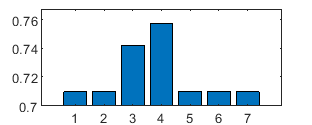

% 读取
load("StructureGA_list.mat",'x_list')
Eff_avg = zeros(1,length(x_list));
parfor ii=1:length(x_list)
    Eff_avg(ii) = FigureOfMerit1D(x_list{ii},OptParm);
end
figure('Position',[0 0 250 100])
bar(Eff_avg);
ylim([min(Eff_avg)-0.01,max(Eff_avg)+0.01])